Reading in data

imread("data32\test\animal animal_faces cat cat_face\0BGPHALKEI6K.jpg", "jpg")

ans = 32×32×3 uint8 array
ans(:,:,1) =

   164   171   166   159   159   150   150   145   137   140   117    76    61    72    84    86    90    90    90    88    89    87    87    89    88    90    88    87    84    76    77    72
   170   172   169   158   159   155   150   143   140   141   116    75    59    71    83    86    87    88    89    88    90    92    92    88    90    93    92    86    84    82    79    71
   152   173   172   164   157   150   148   141   137   139   114    76    62    71    80    82    81    80    86    92    92    88    90    93    90    88    82    83    80    83    69    71
   150   172   165   160   156   151   146   142   136   140   116    76    62    72    79    82    80    80    85    89    90    95    95    87    85    88    81    80    76    72    72    70
   149   169   167   158   156   147   139   138   135   140   118    76    60    71    81    83    79    82    85    89    91    92    90    86    81    76    87   137   136    74    65  


imagefiles = dir("data32\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1661×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data32\test\animal animal_faces cat cat_face"

filepath = "data32\test\animal animal_faces cat cat_face"

for ii=1:50
   currentfilename = imagefiles(ii).name;
   currentimage = imread(filepath + "\" +  currentfilename);
   images{ii} = currentimage;
end

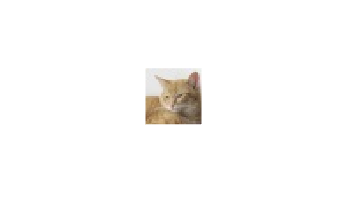

imshow(images{1})

Reproduce image

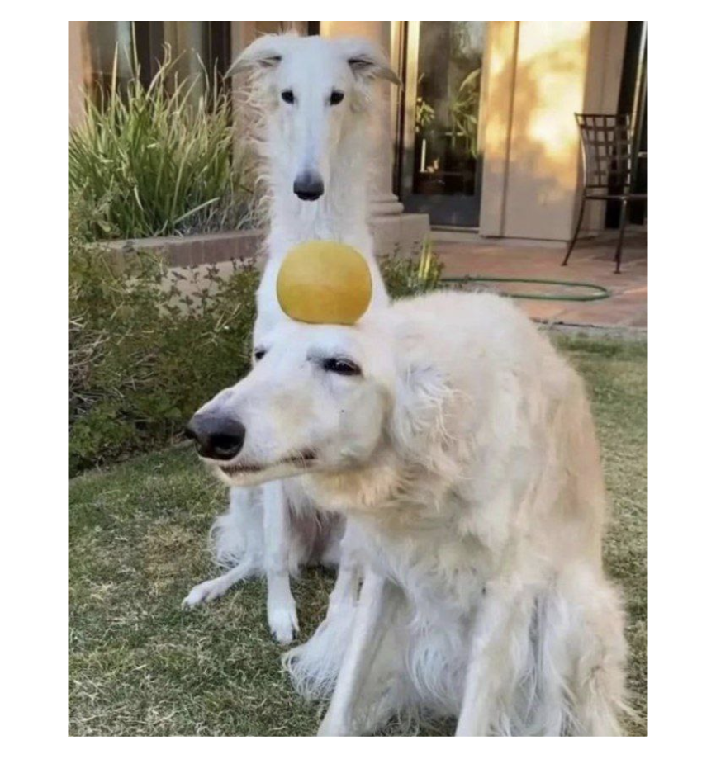

targetImage = imread("dogdogorange.png");

imshow(targetImage)


[l, h, d] = size(targetImage)

l = 867

h = 701

d = 3

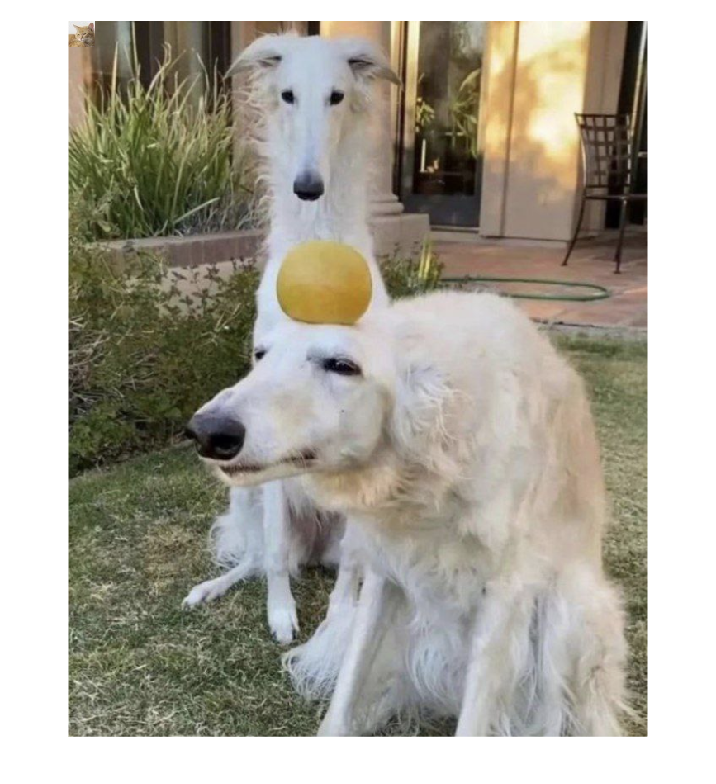


targetImage(1:32, 1:32, :) = images{1};

imshow(targetImage)

Image Segmentation

Use kmeans with random clustters to segment the image 

segmentedImage = im2double(targetImage)

segmentedImage = segmentedImage(:,:,1) =

    0.9255    0.9020    0.9098    0.9059    0.8863    0.8784    0.8980    0.8980    0.9098    0.9216    0.9176    0.9137    0.9137    0.9176    0.9137    0.8941    0.9020    0.9059    0.8902    0.8941    0.8980    0.9137    0.9137    0.9176    0.9098    0.8980    0.9294    0.9176    0.9176    0.9255    0.9294    0.9294    0.4235    0.4275    0.4157    0.4000    0.3882    0.3804    0.3804    0.3804    0.3843    0.3922    0.3922    0.3922    0.3922    0.3922    0.3922    0.3922    0.3882    0.3843    0.3843    0.3922    0.4000    0.4118    0.4157    0.4235    0.4353    0.4510    0.4627    0.5059    0.5569    0.5882    0.5882    0.5804    0.5765    0.5765    0.5804    0.5725    0.5490    0.5137    0.4824    0.4667    0.4471    0.3765    0.2824    0.2549    0.3216    0.4588    0.4863    0.3529    0.2118    0.1647    0.1608    0.1608    0.1569    0.1569    0.1569    0.1608    0.1647    0.1647    0.1686    0.1686    0.1686    0.1765    0.1804    0.16

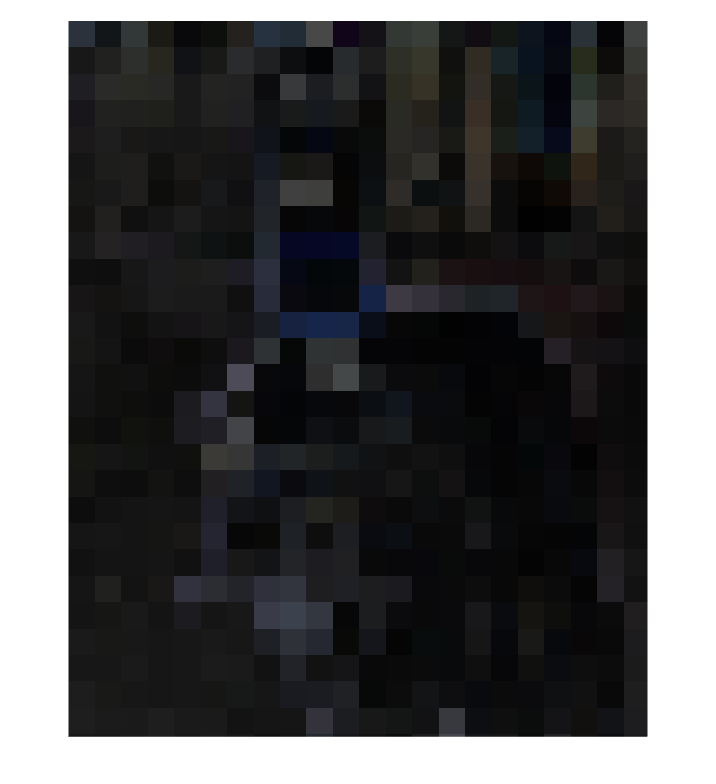

for i = 1:3
segmentedImage(:,:,i) = segmentImage(segmentedImage(:,:,i));
end

imshow(segmentedImage)

Big Loop

rTileSize = 32;
oTileSize = 32;
[~, datasetSize] = size(images)

ans =      1    50


[rows, cols] = size(targetImage)

rows = 867

cols = 2103

tileRows = ceil(rows / oTileSize)

tileRows = 28

tileCols = ceil(cols / oTileSize)

tileCols = 66

% go through each tile
for r = 1:tileRows
    for c = 1:tileCols
        % find best image for each tile
        for i = 1:datasetSize

        end

    end
end

Segment image into 32 bit chunks and standard deviate colours

function output = segmentImage(img)
img = im2double(img);

blockSize = [32, 32]; % går att byta
output = blockproc(img, blockSize, @processBlock);

end

%skum dokumentation
function outBlock = processBlock(blockStruct)
    originalBlock = blockStruct.data;
        stdValue = std2(originalBlock);
        outBlock = stdValue * ones(size(originalBlock), 'like', originalBlock);
end